## **Lab 1: Kuan-Wei Lee**

**Partner: Megan Miyasaki**

## **A little statistics **

1-B: Converting a probabilty into sigma

The code below integrate a normal distribution fro -infinity to a point x = Z, where Z is the Z score chosen. I set Z score to be "1.04 sigma" just for fun.

clear all
close all
clc
%doesm't change anything but I like to have ; at the end of each line.
mu = 0;
sigma = 1;

x = -1:0.001:1;

pd2 = pdf('Normal',x,mu,sigma);
plot(x,pd2)

P = normcdf(1.04*sigma,mu,sigma);

P = 0.8508(Probability of getting value that is smaller than x = 1.04*sigma)

This matches the values on the Z table

1-C: Given the probability, find the associated sigma value

I chose the probability to be 0.84134. According to the Z table, the associated sigma value should be 1.

p = 0.84134;
X = norminv(p,mu,sigma)

X = 1.0000

X = 1*sigma, where sigma = 1

This means that the probability of getting a value greater than 1 sigma is 0.84134, which is consistant with the z table. 

**possibly explain this a little more to me**

1-D: Explain the meaning of the minus sign that appears

p = 0.4;
X = norminv(p,mu,sigma)

X = -0.2533

X is the distance away from the mean in terms of sigma. If the probability is smaller than 0.5, X will be on the left of the mean because the probability of getting a value smaller than X will be smaller 0.5. In terms of sigma, X will be a negative value of sigma because it is "-c*sigma" away from the mean.

In this case: p = 0.4 and c is thus 0.2533

2-B: Make plots of lognormal distribution

Lognormal distribution was made with "random" and the function "makedist":

clear vars
clc
close all
x = random('Lognormal',1.,0.5,[1 100000])

x =     1.2988    3.6938    7.0273    3.3497    3.7189    4.1317    0.7367    3.6104    5.2160    1.4267    2.5025    4.8621    1.7643    4.0364    6.0313    2.3560    1.9528    1.7106    3.9947    3.6704    3.9683    1.8677    4.7238    1.9420    2.7956    0.9785    7.4928    1.8775    6.3076    4.8246    5.8896    1.8511    1.4694    2.0287    2.2366    6.0934    1.8364    0.4197    1.2296    3.5344    5.1510    2.8194    3.4206    4.4033    5.1738    1.9245    1.8763    2.7389    1.1697    4.9427


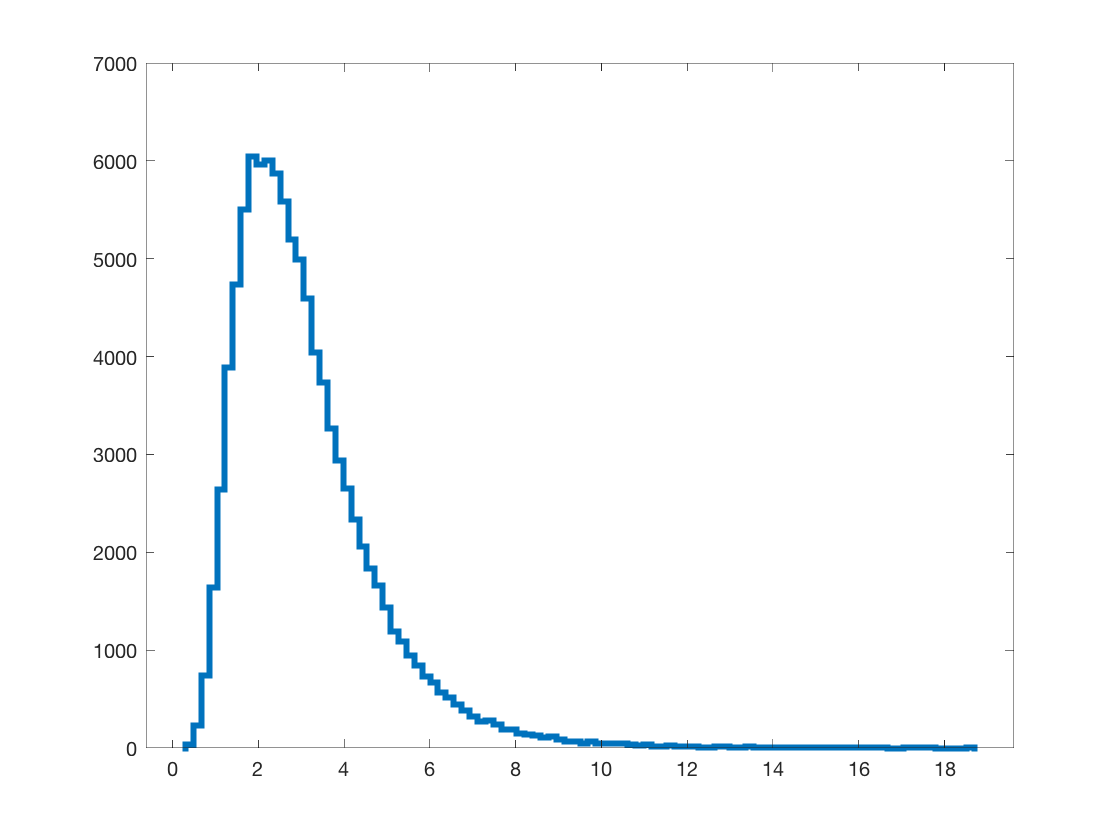

histogram(x,100,'DisplayStyle',"stairs",'LineWidth',3)

% xlim([0 100])
x2 = linspace(0,10,1000);
%i think you need 100k samples so u might wanna add more - megan
pd = makedist("Lognormal","mu",1.,"sigma",0.5);
histogram(x,100,'DisplayStyle',"stairs",'LineWidth',3,'Normalization','pdf')
hold on
plot(x2,pdf(pd,x2),"LineWidth",2);
% xlim([0 600])
d = random('Normal', 5., 0.01, [1,100000]);
%why do u have a d, it doesnt look like used it here - megan

3. Imagine that your signal-free data follows the distribution you have chosen; and you have a measurement for which you need to determine the 'sigma

3-A

Lognormal distribution was chosen for the signal free data

Hypothetical measurement is decided to be 5

3-B

The statistical question is: The probability of the background giving me a data point that looks as or more signal like thatn (**than)** the reading I have is the same probability as if my data was Gaussina (**gaussian)** and I was X$\sigma$ away from the mean. What would be the value of X if the measurement is 5?

3-C

Integral to solve this problem:


$$\int_{-\infty }^{X\sigma } \frac{1}{\sigma \sqrt{2}}e^{\frac{-{\left(x-\mu \right)}^2 }{2\sigma^2 }} \textrm{dx}=\int_0^a P\left(x\right)\textrm{dx}$$



$$P\left(x\right)=\frac{1}{S\sqrt{2}\pi }e^{-\frac{\left(\textrm{lnx}-M^2 \right)}{\left(2S^2 \right)}}$$



$$\begin{array}{l}
\mu =e^{M+\frac{S^2 }{2}} =1\\
\sigma^2 =e^{S^2 +2M} \left(e^{S^2 } -1\right)=0\ldotp 5
\end{array}$$


3-D

The code below evaluate the integrals and find X

prob = cdf('Lognormal',5,1,0.5)

prob = 0.8886

mu = 0;
sigma = 1;
x_sigma = (icdf('Normal',prob,mu,sigma)-mu)/sigma

x_sigma = 1.2189

% X = x_sigma = 1.2189

X = 1.2189

prob2 = cdf('Lognormal',6,1,0.5)

prob2 = 0.9433

x_sigma2 = (icdf('Normal',prob2,mu,sigma)-mu)/sigma

x_sigma2 = 1.5835

The hypothetical measurement is changed from 5 to 6. The value of the integral increases and the value of X also increases. Since the integral is integrated from negatice infinity to the data point, moving further right to the mean will increase the area under the curve. Moving further right also means that the data point is further away from the mean so the value of X goes up.

## **Non-Continuous distributions**

1-B

pd =   PoissonDistribution

  Poisson distribution
    lambda = 1


pd =   PoissonDistribution

  Poisson distribution
    lambda = 2


pd =   PoissonDistribution

  Poisson distribution
    lambda = 3


pd =   PoissonDistribution

  Poisson distribution
    lambda = 4


pd =   PoissonDistribution

  Poisson distribution
    lambda = 5


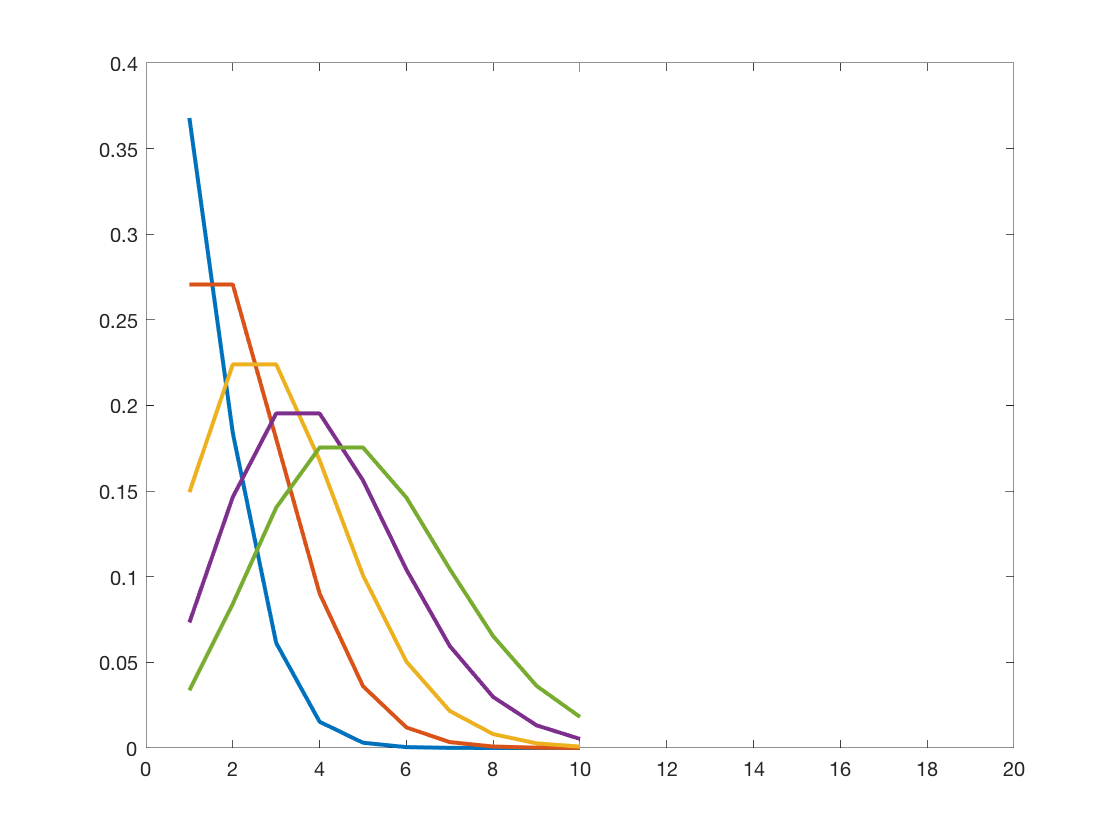

clear all
close all
clc


x = 1:1:10;
for i = 1:5
    pd = makedist('Poisson','lambda',i)
    plot(x,pdf(pd,x),'LineWidth',2)
    hold on
    xlim([0 20])
end

Poisson distribution is ploted in this section

Different parameter 'Lambda' is used to generate the plots

Poisson distribution with higher lambda value has lower peak and wider distribution

1-C

Statistical question:The probability of the background giving me a data point that looks as or more signal like thatn **(than)** the reading I have is the same probability as if my data was Gaussina **(Gaussian)** and I was X$\sigma$ away from the mean. What would be the value of X if the measurement is 5? Assuming the background has poisson districution with lambda = 5

Lambda = 5;
sigma = 1;
mu = 0;
x = 4;
prob = cdf('Poisson',x,Lambda)

prob = 0.4405

x_sigma = (icdf('Normal',prob,mu,sigma)-mu)/sigma

x_sigma = -0.1497

X = -0.1497

This suggests that the probability that a background give me a reading that is as or more signal like is 0.5596. **possibly explain this a little more to me**

1-D

The distribution being discrete means that the probability of getting a non-integer measurement is 0. For example, the probability of getting 2.5 gamma impulses in 1ms is 0 because the counts of impulses are integers. 

1-E

Although the measurement are diecret integers, the mean can be an non-integer because it is a parameter that can be continuous.  **possibly explain this a little more to me**